% Autor: Wirley Almeida
% 13/10/2021
% Introdução à Programação com MATLAB
% Semana 7
% For-Loops

clear; clc; close all;

total = 0;
for n = 1:5
    total = total + n;
end
fprintf('total equals %d\n',total);

total equals 15


sumintup(5)

total equal 15


sumintup(10)

total equal 55


sumintup(100)

total equal 5050


list = rand(1,5);
for x = list
    if x > 0.5
        fprintf('Random number %f is large.\n',x);
    else
        fprintf('Random number %f is small.\n',x);
    end
end

Random number 0.814724 is large.
Random number 0.905792 is large.


Random number 0.126987 is small.


Random number 0.913376 is large.
Random number 0.632359 is large.


for x = rand(1,5)
    if x > 0.5
        fprintf('Random number %f is large.\n',x);
    else
        fprintf('Random number %f is small.\n',x);
    end
end

Random number 0.141886 is small.
Random number 0.421761 is small.


Random number 0.915736 is large.
Random number 0.792207 is large.
Random number 0.959492 is large.


loop_test(5)

n = 1

n = 2

n = 3

n = 4

n = 5

Total: 20


u = [5 4 8 8 2];
v = [5 5 7 8 8];
w = u - v

w =      0    -1     1     0    -6


for ii = 1:length(u)
    w(ii) = u(ii) - v(ii);
end
w

w =      0    -1     1     0    -6


fibo(10)

Fibonacci numbers:
     1     1     2     3     5     8    13    21    34    55



A = randi(10,3,4)

A =     10     3     6    10
     4     8     7     6
     6     3     9     2


P = A.*A

P =    100     9    36   100
    16    64    49    36
    36     9    81     4


mul

Working on row 1...
(1 1)
(1 2)
(1 3)
(1 4)
Working on row 2...
(2 1)
(2 2)
(2 3)
(2 4)
Working on row 3...
(3 1)
(3 2)
(3 3)
(3 4)


asterisks

*
**
***
****
*****
******
*******


Exemplos do livro Computer Programming with MATLAB, páginas 149-54

Uso do for para processamento de imagens

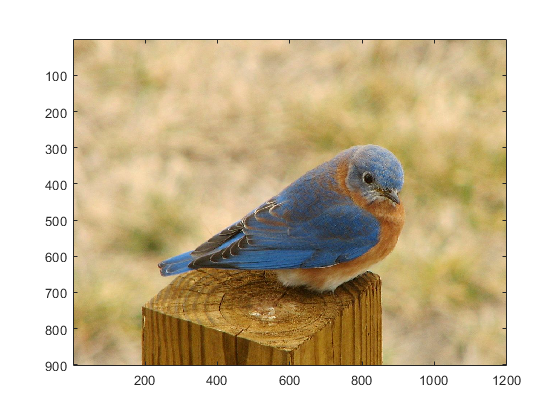

bluebird = imread('1200px-Eastern_Bluebird.jpg');
image(bluebird)
axis equal
axis tight

dims = size(bluebird)

dims =          902        1200           3


redbird = bluebird;
dims = size(bluebird);
for ii = 1:dims(1)
    for jj = 1:dims(2)
        if bluebird(ii,jj,3) > mean(bluebird(ii,jj,:))
            redbird(ii,jj,1) = bluebird(ii,jj,3);
            redbird(ii,jj,2:3) = 0;
        end
    end
end

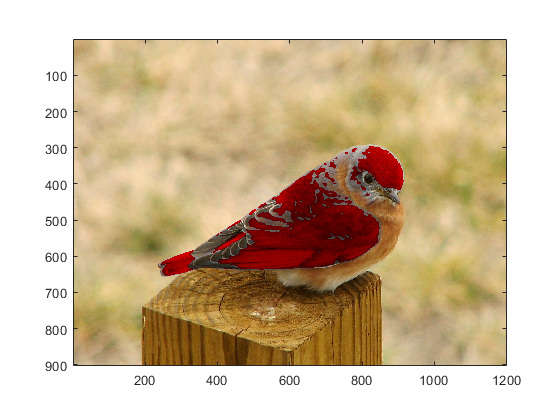

image(redbird)
axis equal
axis tight

imwrite(redbird,'red_bluebird.png','png')

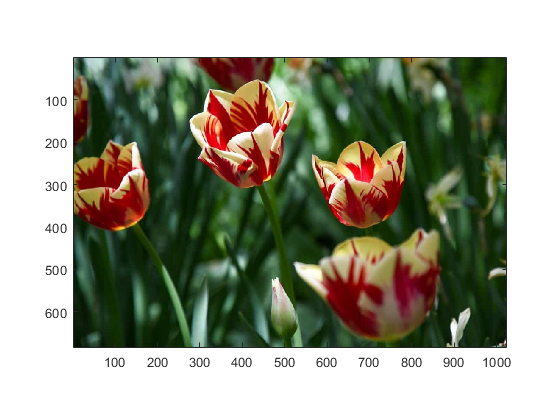

flower = imread('Tulips-GPI-051320-1024x683.jpg');
image(flower)
axis equal
axis tight

wide_flower = flower;
dims = size(flower);
for ii = 1:dims(1)
    for jj = 1:dims(2)
        wide_flower(ii,jj,:) = flower(ii,round(jj/1.2),:);
    end
end

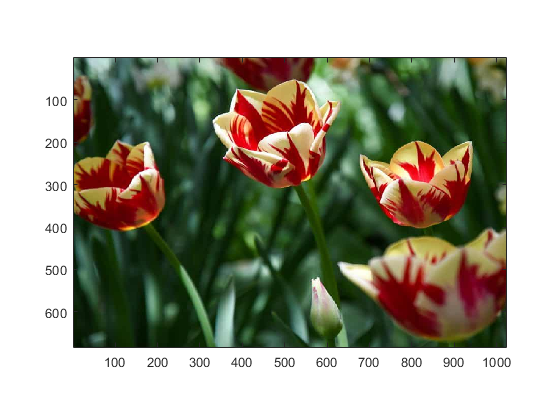

image(wide_flower)
axis equal
axis tight

imwrite(wide_flower,'wide_flower.png','png')